# 2.3 Cellular segmentation and H3-K27M values assignment

This script is used for segment the already aligned cells

The fist step is to specify the path of the file analysed

## Finding spots Image1

We load the image containnig IF on Itop.

SAMP='MGH666641';

SAMP = 'MGH666641'

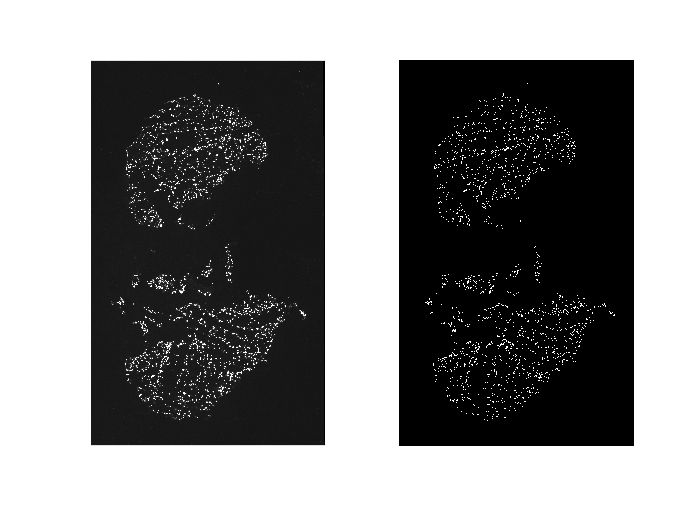

folder=['X:\DIPG_Human\NUTSHELL_DIPG\',SAMP,'\'];
PREFIX=['IF_',SAMP,'_ALI_'];
xleft=0;
yup=0;
Itop=imread([folder,PREFIX,num2str(2),'.tif']);
%Itop=imresize(Itop,2);
Itop=Itop(15000:35430,:);

We can now read and segment the cells using watershed

IDAPI=imread([folder,PREFIX,num2str(1),'.tif']);
Dapi = imadjust(IDAPI); % contrast enhancement
ImSz = size(Dapi);
Debug = 1;
%% threshold the map
ThreshVal =30000;
bwDapi = imerode(Dapi>ThreshVal, strel('disk', 2));

if Debug
    figure(300)
    subplot(2,1,1);
    imagesc(Dapi); 
    subplot(2,1,2);
    imagesc(bwDapi);
    colormap bone
    fprintf('Threshold = %f\n', ThreshVal);
    linkaxes();
end

Threshold = 30000.000000


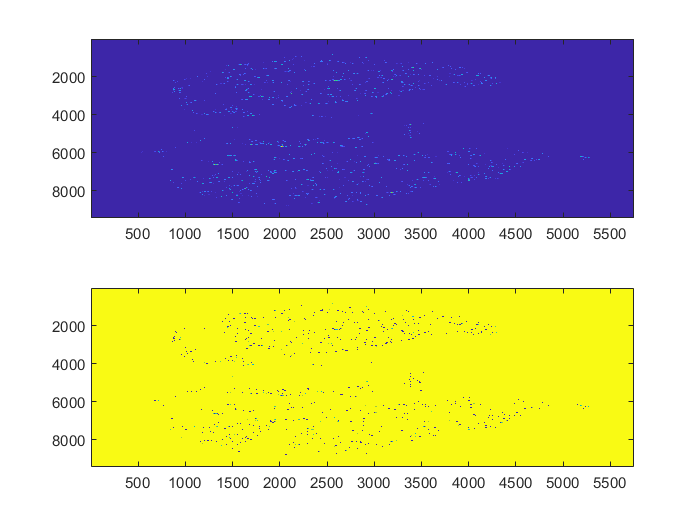


%% find local maxima 
dist = bwdist(~bwDapi);
dist0 = dist;
dist0(dist<5)=0;


ddist = imdilate(dist0, strel('disk', 7));
%clear dist 
impim = imimposemin(-dist0, imregionalmax(ddist));
clear dist0
if Debug
    figure();
    subplot(2,1,1)
    imagesc(dist);
    subplot(2,1,2)
    imagesc(impim);
end

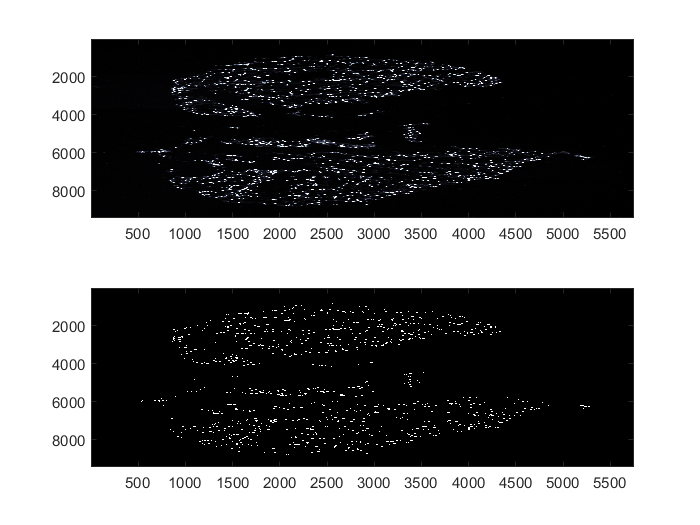

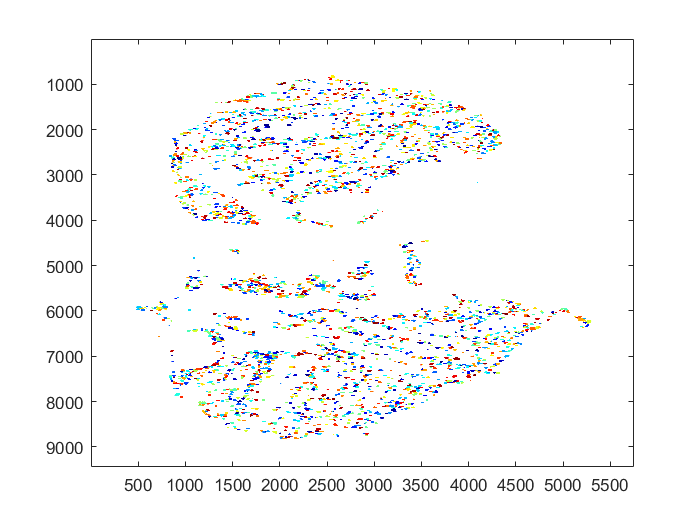

%% segment
% remove pixels at watershed boundaries
bwDapi0 = bwDapi;
bwDapi0(watershed(impim)==0)=0;

% assign all pixels a label
labels = uint32(bwlabel(bwDapi0));
[d, idx] = bwdist(bwDapi0);

% now expand the regions by a margin
CellMap0 = zeros(ImSz, 'uint32');
Expansions = (d<10);
CellMap0(Expansions) = labels(idx(Expansions));

% We save the segmenation mask in the CellMap0 object. That will be used
% later on for assigning reads to cells in 2.3.
save(['X:\DIPG_Human\NUTSHELL_DIPG\',SAMP,'\',SAMP,'_CellMap'],"CellMap0")%,'-v7.3')
load(['X:\DIPG_Human\NUTSHELL_DIPG\',SAMP,'\',SAMP,'_CellMap'],"CellMap0")


figure();
%subplot(1,2,1)
imagesc(label2rgb(CellMap0, 'jet', 'w', 'shuffle'));
hold on
subplot(1,2,2)
imshow(IDAPI*20);
linkaxes();

% We extract the information of every cell, including the XY position
U2=CellMap0;
blobs = unique(U2);
blobs = blobs(blobs~=0);
size(blobs)
XtotD=[];
YtotD=[];
Position1=[];
SIZE=[];
rp = regionprops(CellMap0);
CellYX = fliplr(vertcat(rp.Centroid));        
k=find(ismember(U2,blobs));
CELL=U2(k);

% We use regionprops pairing the segmentation mask with the image
% containing the IF (Itop) to extract the mean and max values of H3-K27M of
% every cell.
IF_intensity=regionprops(CellMap0,Itop,"MeanIntensity","Centroid","MaxIntensity");
CellYX = fliplr(vertcat(IF_intensity.Centroid));
Max_Intensity = fliplr(vertcat(IF_intensity.MeanIntensity));
CELL_LOC(:,1)=CellYX(:,1);
CELL_LOC(:,2)=CellYX(:,2);
CELL_LOC(:,3)=Max_Intensity(:,1);
CELL_LOC=array2table(CELL_LOC);
blobs = unique(U2);
CELL_LOC(:,4)=array2table(blobs(2:end,:));
CELL_LOC.Properties.VariableNames={'X','Y','IF_mean_int','ID'};
writetable(CELL_LOC,['X:\DIPG_Human\NUTSHELL_DIPG\',SAMP,'\DIPG_',SAMP,'_IFSCORES.csv'])

Integrate MATISSE to assign IFs to reads. 


decoded_file = ['X:\DIPG_Human\NUTSHELL_DIPG\decoded_',SAMP,'_1_metric_JULY3N.csv'];
image = ['X:\DIPG_Human\NUTSHELL_DIPG\',SAMP,'\Base_1_stitched-1.tif'];   
scale=1; 
SPOTS1=ISS_getspots(decoded_file,'genecolumn',13,'XYcolumn',[10,11]);
SPOTS1.image=image;
SPOTS1.scale=scale;
ALLSPOTS.SPOTS1=SPOTS1;
SPOTS=fill_matisse(ALLSPOTS);
SPOTS.location=SPOTS.location/0.1625


show_spots(SPOTS);

CORTEX_SPOTS2=SPOTS;
CORTEX_SPOTS2.Cellmaps{1}=CellMap0;

U2=CellMap0;
blobs = unique(U2);
blobs = blobs(blobs~=0);
size(blobs);
XY=fliplr(vertcat(regionprops(CellMap0).Centroid));

CORTEX_SPOTS2.centroidpos{1}=XY;
CORTEX_SPOTS2.centroidID{1}=blobs;

CORTEX_SPOTS2.location(:,2)=CORTEX_SPOTS2.location(:,2)-15000;
figure;
imagesc(label2rgb(CellMap0, 'jet', 'w', 'shuffle'));
hold on
gscatter(CORTEX_SPOTS2.location(:,1),CORTEX_SPOTS2.location(:,2),CORTEX_SPOTS2.spotname);

[CELLS,READS_ASSIGNED]= define_cellsIF(CORTEX_SPOTS2);


We can now remove the IF data that has no related reads

SELS=ismember(CELL_LOC.ID,CELLS.spotname);
CELL_LOC=CELL_LOC(SELS,:);

Finally we save our results, as a cellxgene table, as well as the read to cell assignment

IF_RESULTS=CELLS.expressionmatrix;
IF_RESULTS=array2table(IF_RESULTS);
IF_RESULTS.Properties.VariableNames=CELLS.expressionnames;
IF_RESULTS.X=CELLS.location(:,1);
IF_RESULTS.Y=CELLS.location(:,2);
IF_RESULTS.Cell_ID=CELLS.spotname;
IF_RESULTS.Y_IF=table2array(CELL_LOC(:,1));
IF_RESULTS.X_IF=table2array(CELL_LOC(:,2));
IF_RESULTS.mean_IF=table2array(CELL_LOC(:,3));
IF_RESULTS.IF_Cell_ID=table2array(CELL_LOC(:,4));

writetable(IF_RESULTS,['X:/DIPG_Human/NUTSHELL_DIPG/',SAMP,'/',SAMP,'_CELLS_reads_ISS_and_IF.csv']);
writecell(READS_ASSIGNED,['X:/DIPG_Human/NUTSHELL_DIPG/',SAMP,'/',SAMP,'_READS_position_and_CELL_assigned_ISS_and_IF.csv']);